# **TRATAMIENTO DIGITAL DE IMAGENES**

#### **Máster Universitario en Visión Artificial (URJC). **

## **Autor: Vicente Gilabert Mañó**

**Práctica 1: Análisis en el dominio de la frecuencia**

**1.B.- 2.A.- Calcular la DCT 2D de una imagen en escala de grises en bloques de 8x8 píxeles y probar el resultado de comprimir con diferentes porcentajes de compresión. El factor de compresión lo simularemos mediante diferentes configuraciones de las máscaras como las mostradas en la Figura 1. Por ejemplo, la de la izquierda tiene un nivel de compresión de 1/64, mientras que la de la derecha de 10/64. Comparar los resultados obtenidos, al menos para los factores de compresión citados. Comente los resultados obtenidos.**

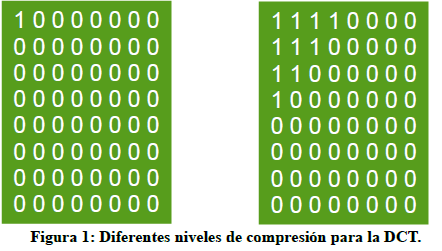

Para la realización de la práctica, se han desarrollado la siguientes funciones:

- **MyBlocksDCT2(img,N,mask):** Calcular la tranformada discreta del coseno (2D) a la imagen de entrada (img), mediante bloques de tamaño (NxN) y aplicando en cada bloque una máscara (mask). → Salida: imagenDCT.

- **MyBlocksIDCT2(img_DCT,N):** Calcular la tranformada inversa discreta del coseno (2D) a la imagen de entrada (img_DCT), mediante bloques de tamaño (NxN). → Salida: imagen espcial comprimida.

- **GenerateMaskDCT(N,c):** para la generacion de las macaras del nivel de compresion. Donde N es el tamaño de la mascara (NxN) y c es el numero de filas y columnas con valor 1. Por ejemplo para la figura 1, en la izquierda tendriamos un c=1 y en la derecha un c=4.

La práctica se separa en tres secciones diferentes:

- (1) Se muestra el código para realizar una compresión a una imagen con un factor 1/64 y se muestran los resultados.

- (2) Se muestra el código para realizar una compresión a una imagen con un factor 10/64 y se muestran los resultados.

- (3) Se comentan unas concluciones de la práctica.

## (1) COMPRESION DE UNA IMAGEN CON UN FACTOR 1/64.

Tamaño del bloque = 8.

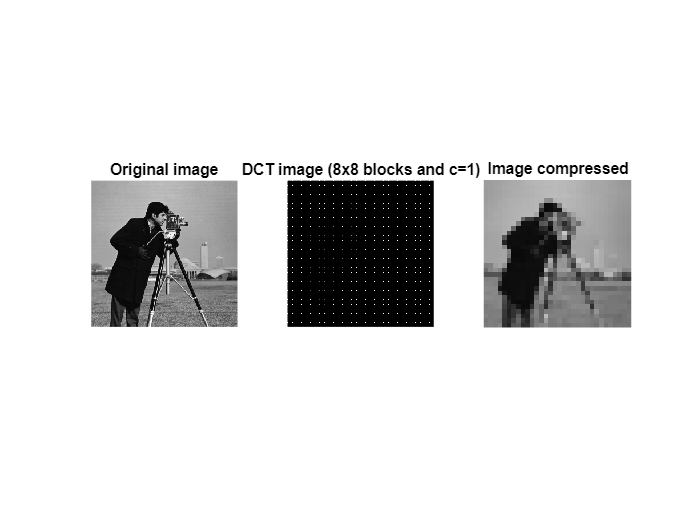

%% Clear Space and load image.
clear all; clc; close all;

% Load and get size of image. Convert to gray if is color image.
img = imread('cameraman.tif');
imgSize = size(img);
if length(imgSize)==3
    img = double(rgb2gray(img));
else
    img = double(img);
end

% Parameters
N = 8; % Size of block procesing (NxN).
c = 1; % Size of compresion matrix. c=1 -> we keep only 1 value per block.

% Generate DCT mask to apply to each block.
mask = GenerateMaskDCT(N,c);

% Apply DCT2 transform to img using NxN block and filtering each block with mask.
img_DCT = MyBlocksDCT2(img,N,mask);
% Apply IDCT2 transform to img_DCT using NxN block. 
% We get a compressed image.
img_comp = MyBlocksIDCT2(img_DCT,N);

%% Subplot representation of space and frequency domains.
figure
subplot(1,3,1)
imshow(uint8(img))
title('Original image')
subplot(1,3,2)
imshow(uint8(img_DCT))
formatSpec = 'DCT image (%dx%d blocks and c=%d)';
str = sprintf(formatSpec,N,N,c);

title(str)
subplot(1,3,3)
imshow(uint8(img_comp))
title('Image compressed')

## (2) COMPRESION DE UNA IMAGEN CON UN FACTOR 10/64.

Tamaño del bloque = 8.

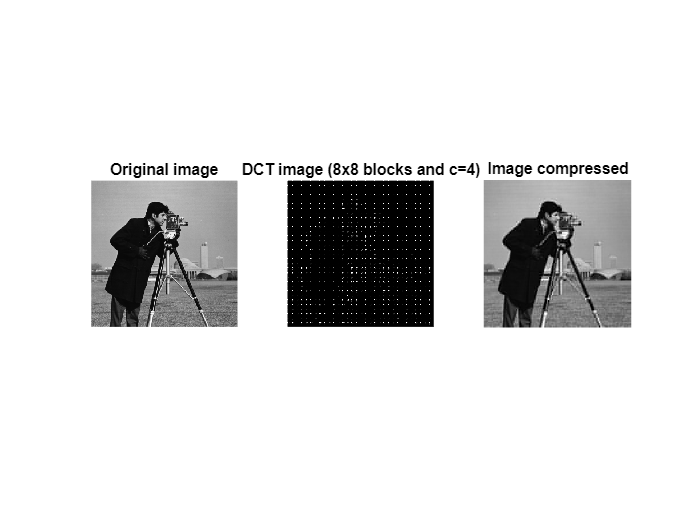

%% Clear Space and load image.
clear all; clc; close all;

% Load and get size of image. Convert to gray if is color image.
img = imread('cameraman.tif');
imgSize = size(img);
if length(imgSize)==3
    img = double(rgb2gray(img));
else
    img = double(img);
end

% Parameters
N = 8; % Size of block procesing (NxN).
c = 4; % Size of compresion matrix. c=4 -> we keep only 10 values per block.

% Generate DCT mask to apply to each block.
mask = GenerateMaskDCT(N,c);

% Apply DCT2 transform to img using NxN block and filtering each block with mask.
img_DCT = MyBlocksDCT2(img,N,mask);
% Apply IDCT2 transform to img_DCT using NxN block. 
% We get a compressed image.
img_comp = MyBlocksIDCT2(img_DCT,N);

%% Subplot representation of space and frequency domains.
figure
subplot(1,3,1)
imshow(uint8(img))
title('Original image')
subplot(1,3,2)
imshow(uint8(img_DCT))
formatSpec = 'DCT image (%dx%d blocks and c=%d)';
str = sprintf(formatSpec,N,N,c);

title(str)
subplot(1,3,3)
imshow(uint8(img_comp))
title('Image compressed')

## **(3) CONCLUSIONES**

- La transformada de coseno, agrupa en la esquina superior izquierda los valores más importantes de la imagen o bloque. Por lo que manteniendo ciertos pixeles cercanos al (0,0) para cada bloque se consigue realizar una compresión de imágenes. 

- Se han implementado las funciones necesarias para realizar las transformadas directas e inversas de coseno mediante bloques. Estas funciones están preparadas para procesar a diferentes tamaños de bloques, y diferentes niveles de compresión que el usuario podrá modificar para su aplicación.

- Se muestran los resultados comparativos de una compresión 1/64 a la izquierda y otra de 10/64 a la derecha:

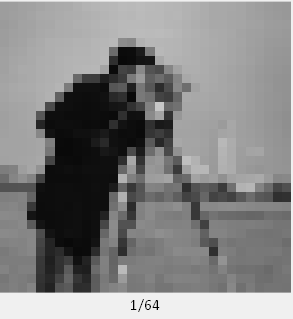  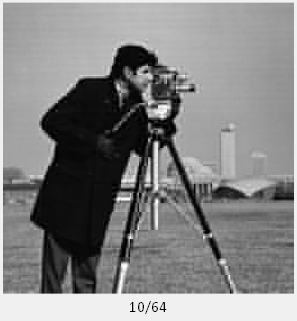

- En la imagen de la derecha estamos guardando 10/64 pixeles por bloque y el resultado es bastante bueno, ya que seguimos viendo la composición general de la imagen. Por lo que dependiendo de la aplicación nos puede ser útil la compresión más o menos de las imágenes. 

- La utilización de la DCT es muy popular en compresión de imágenes. Por ejemplo, el formato .JPG utiliza esta base con algunas modificaciones.